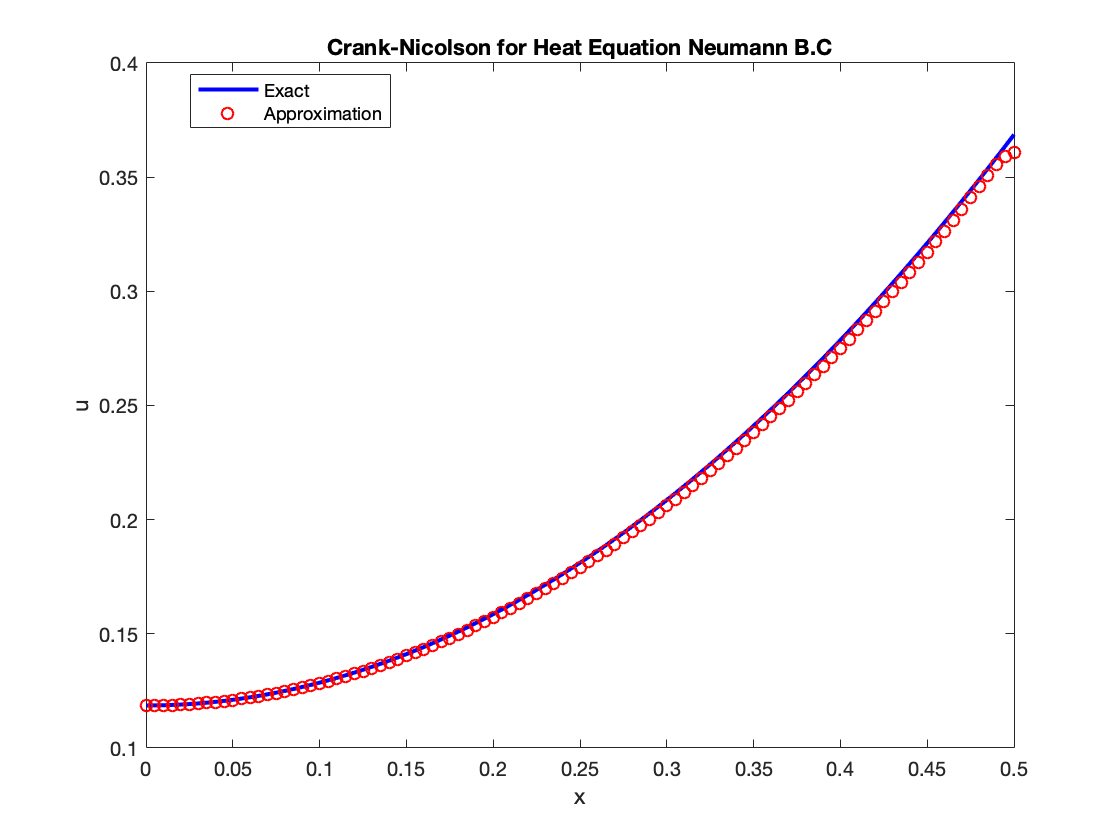

% Crank-Nicolson Scheme for heat equation with Neumann Boundary Conditions
% Problem description
a = 0;
b = 1/2;
m = 100;
dx = (b-a)/m;
x=linspace(a, b, m+1);
dt = dx;
T = 0.1;
N = [1:101];
% The exact solution
u_exact = @(x,t) 2*t+1/2.*((12.*x.^2-1)./6-...
    (2/pi^2).*sum(((-1).^N)./(N.^2).*exp(-4*pi^2.*N.^2.*t)...
    .*cos(2.*N.*pi.*x)));
u0 = zeros(1,m+1);
sigma = dt/dx^2;
% Generate the matrices A and B
A = diag(ones(m+1,1)*(1+sigma))+diag(ones(m,1)*(-sigma/2),1)+...
    diag(ones(m,1)*(-sigma/2),-1);
A(1,2) = -sigma;
A(m+1,m)=-sigma;
B = diag(ones(m+1,1)*(1-sigma))+diag(ones(m,1)*(sigma/2),1)+...
    diag(ones(m,1)*(sigma/2),-1);
B(1,2) = sigma;
B(m+1,m)=sigma;
% Generate vector b
b = zeros(m+1,1);
b(m+1,1)=2*sigma*dx;

U = u0';
T_n = T/dt; % number of time steps
[Lower,Upper,Pivot]= lu(A);
for i = 1:T_n    
    Y = Pivot*(B*U+b);
    X = Lower\Y;
    U = Upper\X;
end
% Plotting the result
plot(x, u_exact(x, T), 'b-', 'LineWidth', 2);
hold on
plot(x, U, 'ro');
hold off
xlabel('x');
ylabel('u');
legend('Exact', 'Approximation', 'Location', 'best');
title("Crank-Nicolson for Heat Equation Neumann B.C")